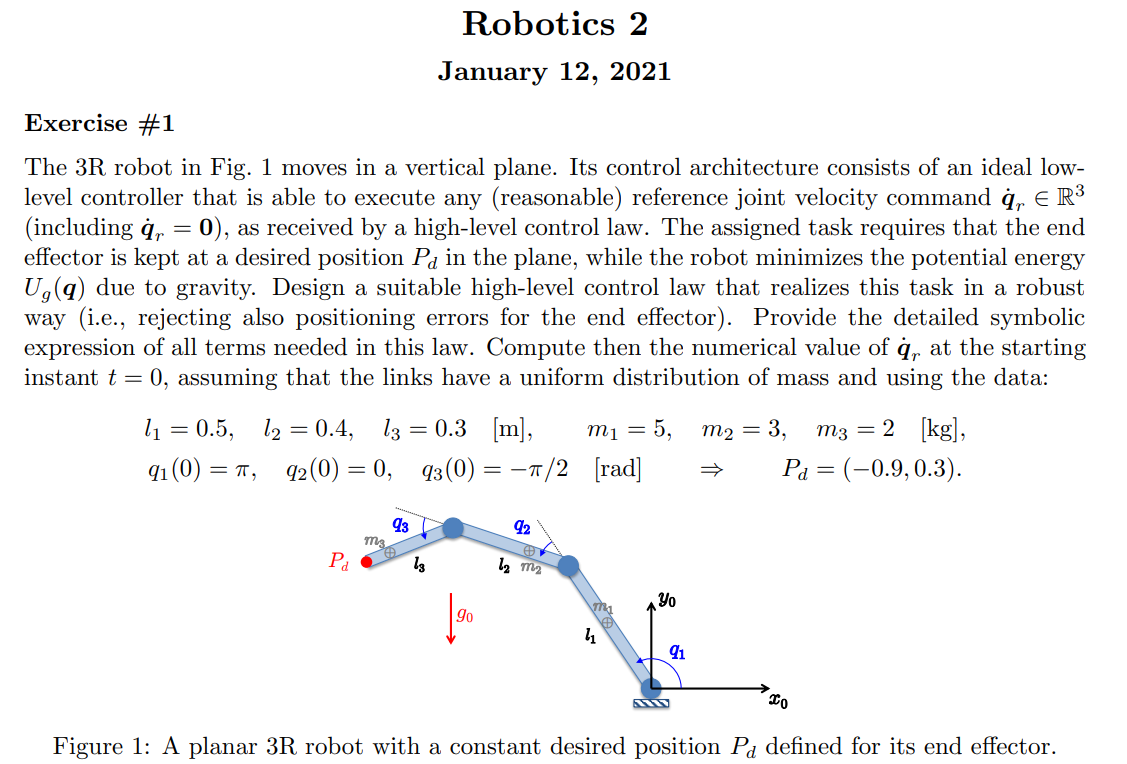

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0,0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['rrr';'xxx';sigmaD]

R2Robot = 3×3 char array
    'rrr'
    'xxx'
    '   '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     


[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     

si falla aquí está el error
method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

$$f = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$J = \begin{array}{l} \left(\begin{array}{ccc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{1} & -l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{1} & -\sigma_{1}\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{2} & l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$V = \left(\begin{array}{c} -l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)-l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right) \end{array}\right)$$

PCVar = struct with fields:
         PTotali: [2×3 sym]
              Pc: [3×3 sym]
              vc: [3×3 sym]
     f_derivated: [1×1 struct]
           f_dot: [2×1 sym]
          f_ddot: [2×1 sym]
          f_tdot: [2×1 sym]
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×3 sym]
               w: [3×3 sym]
               T: [1×1 sym]
              Ti: [1×3 sym]
               M: [3×3 sym]


PC_EEShort = struct with fields:
          f: [2×1 sym]
          J: [2×3 sym]
          V: [2×1 sym]
         Pc: [3×3 sym]
    Pc_ddot: []
    PTotali: [3×3 sym]


VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: [1×1 sym]
    Ti: [1×3 sym]
     M: [3×3 sym]



PC_EEShort.J

$$ans = \left(\begin{array}{ccc} -l_{1}\,s_{1}-l_{2}\,s_{1,2}-l_{3}\,s_{1,2,3} & -l_{2}\,s_{1,2}-l_{3}\,s_{1,2,3} & -l_{3}\,s_{1,2,3}\\ c_{1}\,l_{1}+c_{1,2}\,l_{2}+c_{1,2,3}\,l_{3} & c_{1,2}\,l_{2}+c_{1,2,3}\,l_{3} & c_{1,2,3}\,l_{3} \end{array}\right)$$

PC_EEShort.f

$$ans = \left(\begin{array}{c} c_{1}\,l_{1}+c_{1,2}\,l_{2}+c_{1,2,3}\,l_{3}\\ l_{1}\,s_{1}+l_{2}\,s_{1,2}+l_{3}\,s_{1,2,3} \end{array}\right)$$

VarShortRobot.M

$$ans = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{3}+2\,c_{2}\,l_{1}\,l_{2}\,m_{3}+2\,c_{2}\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}+2\,c_{3}\,{\mathrm{dc}}_{3}\,l_{2}\,m_{3}+2\,c_{2,3}\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3} & \sigma_{3} & \sigma_{1}\\ \sigma_{3} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+c_{3}\,{\mathrm{dc}}_{3}\,l_{2}\,m_{3}+c_{2,3}\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+c_{3}\,l_{2}\,m_{3}\,{\mathrm{dc}}_{3}+I_{3}\\ \sigma_{3}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+c_{2}\,l_{1}\,m_{2}\,{\mathrm{dc}}_{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+c_{2,3}\,l_{1}\,m_{3}\,{\mathrm{dc}}_{3}+m_{3}\,{l_{2}}^{2}+c_{2}\,l_{1}\,m_{3}\,l_{2}+I_{2}+I_{3}\\ \sigma_{4}=2\,c_{3}\,m_{3}\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

angle_desired=[0,0]

angle_desired =      0     0


% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)


% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,q_dot);

## gravity computation

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(PCVar.Pc, z.q, z.l, z.m, z.dc, z.g, z.isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccccccccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{3}\right) & \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$PE = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)$$

$$PE\_short = g_{0}\,s_{1,2}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,s_{1}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,s_{1,2,3}$$

$$g\_q\_short = \left(\begin{array}{c} c_{1}\,g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+c_{1,2,3}\,{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\\ c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+c_{1,2,3}\,{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\\ c_{1,2,3}\,{\mathrm{dc}}_{3}\,g_{0}\,m_{3} \end{array}\right)$$

$$g\_q = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$PE = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)$$

U = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


$$g\_q\_short = \left(\begin{array}{c} c_{1}\,g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+c_{1,2,3}\,{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\\ c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+c_{1,2,3}\,{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\\ c_{1,2,3}\,{\mathrm{dc}}_{3}\,g_{0}\,m_{3} \end{array}\right)$$

$$PE\_short = g_{0}\,s_{1,2}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,s_{1}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,s_{1,2,3}$$

$$ans = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$ans = g_{0}\,m_{2}\,\left({\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)$$

$$ans = g_{0}\,m_{3}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\right)$$

U{1}

$$ans = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

PE_short

$$PE\_short = g_{0}\,s_{1,2}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,s_{1}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,s_{1,2,3}$$

g_q

$$g\_q = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

z.l_=[0.5,0.4,0.3]

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: [0.5000 0.4000 0.3000]
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: [3.1416 0 -1.5708]
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference:

z.dc_=z.l_/2

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: [0.5000 0.4000 0.3000]
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: [3.1416 0 -1.5708]
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference:

z.m_=[5,3,2]

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: [0.5000 0.4000 0.3000]
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: [3.1416 0 -1.5708]
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference:

z.q_=[pi,0,-pi/2]

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: [0.5000 0.4000 0.3000]
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: [3.1416 0 -1.5708]
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference:

to_replace=[z.l',z.dc',z.m',z.q',g0]

$$to\_replace = \left(\begin{array}{ccccccccccccc} l_{1} & l_{2} & l_{3} & {\mathrm{dc}}_{1} & {\mathrm{dc}}_{2} & {\mathrm{dc}}_{3} & m_{1} & m_{2} & m_{3} & q_{1} & q_{2} & q_{3} & g_{0} \end{array}\right)$$

to_replace_=[z.l_,z.dc_,z.m_,z.q_ ,9.8]

to_replace_ =     0.5000    0.4000    0.3000    0.2500    0.2000    0.1500    5.0000    3.0000    2.0000    3.1416         0   -1.5708    9.8000


f_=vpa(subs(f,to_replace,to_replace_))

$$f\_ = \left(\begin{array}{c} -0.9\\ 0.3 \end{array}\right)$$

J_=vpa(subs(J,to_replace,to_replace_))

$$J\_ = \left(\begin{array}{ccc} -0.3 & -0.3 & -0.3\\ -0.9 & -0.4 & 0 \end{array}\right)$$

J_ps_=vpa(subs(J_ps,to_replace,to_replace_))

$$J\_ps\_ = \left(\begin{array}{cc} 0.54644808743169398907103825136612 & -1.1475409836065573770491803278689\\ -1.2295081967213114754098360655738 & 0.081967213114754098360655737704918\\ -2.6502732240437158469945355191257 & 1.0655737704918032786885245901639 \end{array}\right)$$

g_q_=vpa(subs(g_q,to_replace,to_replace_))

$$g\_q\_ = \left(\begin{array}{c} -50.47\\ -13.72\\ 0 \end{array}\right)$$


q_r_dot_= vpa(g_q_-J_ps_*J_*g_q_)

$$q\_r\_dot\_ = \left(\begin{array}{c} -2.5704918032786885245901639344262\\ 5.783606557377049180327868852459\\ -3.2131147540983606557377049180328 \end{array}\right)$$